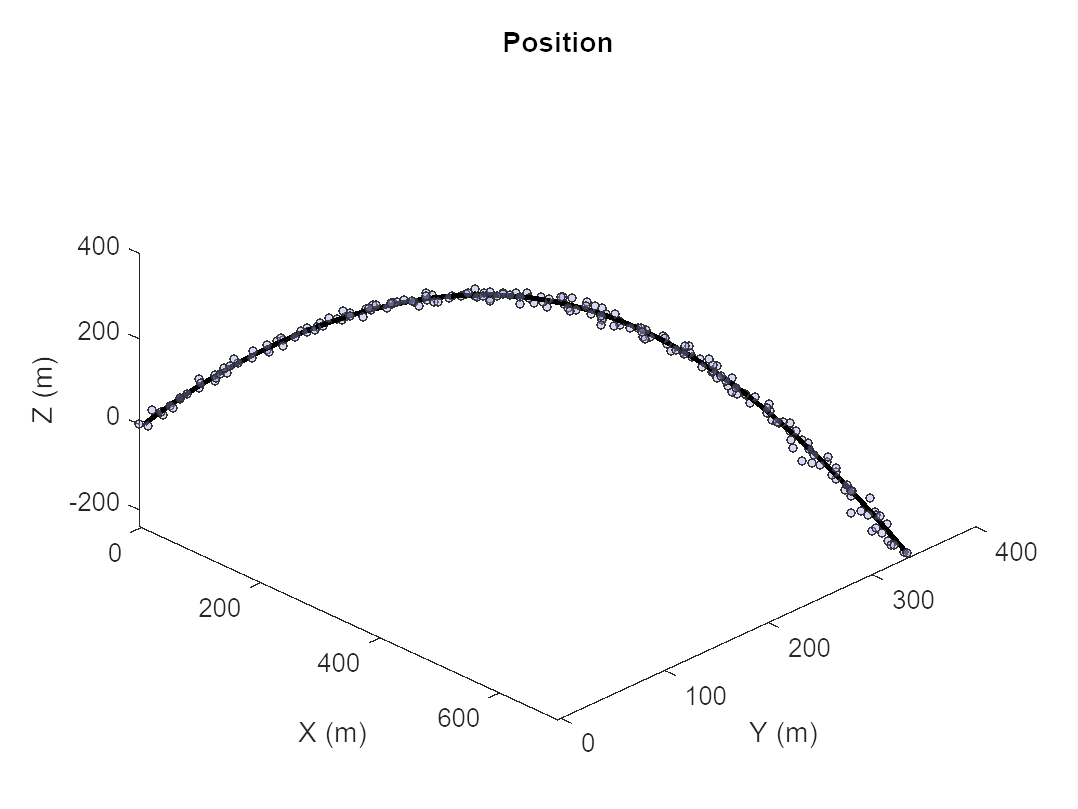



%run a simple model of a falling object in 3D with some inital velocity and a drag parameter
dt = 0.1;  %seconds
t_range = 0:dt:20;
x_start = [0, 0, 0, 50, 20, 100, 0.001];
global m process_noise measurement_noise N
m=1;
N = 7;  %7 dimensions


[T, True_State] = ode45(@rate_func, t_range, x_start);

%generate a noise matrix
pos_noise_sigma = 5;
vel_noise_sigma = 0.5;
measurement_noise = diag([pos_noise_sigma pos_noise_sigma pos_noise_sigma vel_noise_sigma vel_noise_sigma vel_noise_sigma 0]);
%make noisy state by adding random noise to model state
Noisy_State = True_State + randn(size(True_State))*measurement_noise;

%plot
figure(1)
clf

% position

hold on
title("Position")
xlabel("X (m)")
ylabel("Y (m)")
zlabel("Z (m)")
scatter3(Noisy_State(:,1), Noisy_State(:,2), Noisy_State(:,3), 10, "filled", "MarkerFaceColor", [0.6 0.6 0.9], "MarkerEdgeColor", [0.2 0.2 0.2], "MarkerFaceAlpha", 0.4);
plot3(True_State(:,1), True_State(:,2), True_State(:,3), "LineWidth", 2, "Color", "k");
view([45 45])

% velocity



state = Noisy_State(1,:); %init the state with the first raw noisy measurement
state_cov = diag([0.5 0.5 0.5 0.2 0.2 0.2 0.2]); %come up with a dummy State Covariance Matrix to initalize the filter
process_noise = diag([0.023 0.023 0.023 0.02 0.02 0.02 0.0002]);



%============Loop==========
for t = 1:length(t_range)-1

    state_history(t,:) = state;
    measurement = Noisy_State(t,:)';

    [state, state_cov] = kalman_update(state, state_cov, measurement, dt);

end

function [sigma_points] = linear_trajectory_model(sigma_points, dt)
    % state = [x y z vx vy vz Cd/m]
    %linear balistic eqaution with drag
    for i=1:length(sigma_points(:,1))

    sigma_points(:,i) = [1 0 0 dt 0 0 0 ;
                         0 1 0 0 dt 0 0 ;
                         0 0 1 0 0 dt 0 ;
                         0 0 0 1 0 0 -sigma_points(4,i)^2*dt*sign(sigma_points(4,i));
                         0 0 0 0 1 0 -sigma_points(5,i)^2*dt*sign(sigma_points(5,i));
                         0 0 0 0 0 1 -sigma_points(6,i)^2*dt*sign(sigma_points(6,i))-9.8*dt;
                         0 0 0 0 0 0 1] * sigma_points(:,i);
    
    end

end


function [sigma_points] = sensor_model(sigma_points, dt)
    return
end
    
function [state, cov, sigma_points] = unscented_transform(sigma_points, sigma_weights, transfer_function, dt, noise)

    sigma_points = transfer_function(sigma_points, dt);  %popogate points with transfer function
    state = sigma_points * sigma_weights;  %collapse new points to a single state estimate
    cov = ((sigma_points-state)*(diag(sigma_weights)))*((sigma_points-state)') + noise;  %compute the covariance of the new state estimate

end

function [sigma_points, sigma_weights] = make_sigma_points(state, cov, lambda)
global N  
    
    
    
    S = (sqrt((N+lambda))*cov); %can only take square root if Cov = S dot S', then sqrt(cov) = S
    
    
    sigma_points = zeros(N, 2*N+1); %init the Sigma Point matrix (2N+1 by N)
    sigma_weights = zeros(2*N+1, 1);  %init the Sigma Weight matrix (N by 1)

    for i=1:N
        sigma_points(:,i) = state + S(i, i); %front points
        sigma_weights(i,:) = 1/(2*(N+lambda));
    end

    for i=N+1:2*N
        sigma_points(:,i) = state - S(i-N, i-N); %back points
        sigma_weights(i,:) = 1/(2*(N+lambda));
    end

    sigma_points(:,2*N+1) = state; %center point
    sigma_weights(2*N+1,:) = lambda/(N+lambda); %center point
    

end

function [state, state_cov] = kalman_update(state, state_cov, measurement, dt)
global process_noise measurement_noise N
lambda = 3;

%make sigma points and predict new state and covariance
[sigma_points, sigma_weights] = make_sigma_points(state, state_cov, lambda);
[P_state, P_state_cov, P_sigma_points] = unscented_transform(sigma_points, sigma_weights, @linear_trajectory_model, dt, process_noise);
%predict the measurment and measurement covariance
[P_measurement, P_measurement_cov, PP_sigma_points] = unscented_transform(sigma_points, sigma_weights, @sensor_model, dt, measurement_noise);
%compute cross correlation from predicted sate and predicted measurement
cross_correlation = ((P_sigma_points-P_state)*(diag(sigma_weights)))*((PP_sigma_points-P_measurement)');
kalman_gain = cross_correlation/P_measurement_cov;

%update the state and state covariance
state = P_state + kalman_gain*(measurement - P_measurement);
state_cov = (eye(N) - kalman_gain*cross_correlation).*P_state_cov;  %watch for element-wise matrix multiplication!!

end




function rate = rate_func(~, X)

global m

x_pos = X(1);
y_pos = X(2);
z_pos = X(3);
x_vel = X(4);
y_vel = X(5);
z_vel = X(6);
C_D = X(7);

%calculate forces
f_drag_x = C_D * x_vel^2 * sign(x_vel) * -1;
f_drag_y = C_D * y_vel^2 * sign(y_vel) * -1;
f_drag_z = C_D * z_vel^2 * sign(z_vel) * -1;
f_grav_z = -9.8*m;

%calculate derivatives
dxdt = x_vel;
dydt = y_vel;
dzdt = z_vel;
dvxdt = (f_drag_x) / m;
dvydt = (f_drag_y)/ m;
dvzdt = (f_drag_z + f_grav_z) / m;
dC_Ddt = 0;

%construct rate vector
rate = [dxdt ; dydt ; dzdt ; dvxdt ; dvydt ; dvzdt ; dC_Ddt];

end


